**Using Balanced Modulator generate DSBSC signal**

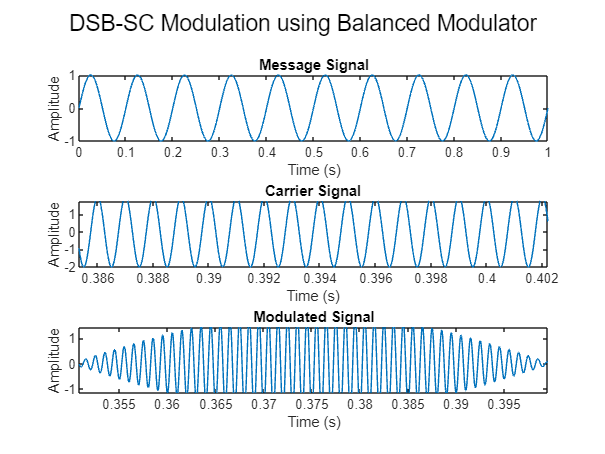

%define parameters
fc=1000;
fm=10;
fs=100000;
t=0:1/fs:1; 
am=1;
ac=2;

%message signal
m=am*sin(2*pi*fm*t);

%carrier signal
c=ac*cos(2*pi*fc*t);

%modulated signal
mod=m.*c;

%plot signals
subplot(3,1,1);
plot(t, m);
title('Message Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, c);
title('Carrier Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, mod);
title('Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

%display the plot
sgtitle('DSB-SC Modulation using Balanced Modulator');